# Midcingulate cortex and action monitoring

### Dependencies

- Gramm toolbox (https://github.com/stevenerrington/toolbox/tree/main/gramm)

## Setup workspace

clear all; clc; % Clear workspace
cd('E:\conflict\analyses\2022-mcc-action')
dirs = get_dirs_mcc('robarts'); % Set directories

getColors_mcc % Define colorschemes
ephysLog = importOnlineEphysLogMaster; % Get recording log

### Curate data

Load in the main pre-processed data map for the 2022-dajo dataset.

dajo_datamap = load_datamap(fullfile(dirs.root,'data'));

Curate the datamap, taking sessions that only match the following criteria:

- Sampled from the midcingulate cortex (ACC)

- Both monkeys (dar and jou)

- Session contained single-unit activity (SPK)

- Electrodes with 50, 100, and 150um intercontact spacing.

dajo_datamap_curated = data_sessionCurate...
    (dajo_datamap,...
    'area', {'DMFC'}, 'monkey', {'dar','jou'}, 'signal', {'SPK'},...
    'spacing', [50, 100, 150]);

In this curated data, there are 1645 valid units, across 34 unique sites, in 131 sessions 



for prb = 1:height(dajo_datamap_curated)
filename = dajo_datamap_curated.dataFilename(prb);
ind = find(contains(ephysLog.Session,filename));
probes(prb) = ephysLog.probeLabel(ind);
end
dajo_datamap_curated.probes = probes';


Once curated, get the names of the relevant behavior and neural files.

dataFiles_beh = unique(dajo_datamap_curated.sessionBeh);
dataFiles_neural = unique(dajo_datamap_curated.dataFilename);

## Behavioural analysis

Extract behavior across all relevant sessions (as identified in the curated dajo_datamap).

Behavior includes: stop behavior, RTs, value behavior.

behavior = mcc_stopping_extractBeh(dirs,dataFiles_beh);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Extracting: dar-cmand1DR-20201127 ... [2 of 83]  
Extracting: dar-cmand1DR-20201229 ... [4 of 83]  
Extracting: dar-cmand1DR-20210115 ... [6 of 83]  
Extracting: dar-cmand1DR-20210213 ... [8 of 83]  
Extracting: dar-cmand1DR-20201126 ... [1 of 83]  
Extracting: dar-cmand1DR-20210211 ... [7 of 83]  
Extracting: dar-cmand1DR-20201213 ... [3 of 83]  
Extracting: dar-cmand1DR-20210112 ... [5 of 83]  
Extracting: dar-cmand1DR-20210419 ... [17 of 83]  
Extracting: jou-cmand1DR-20201129 ... [44 of 83]  
Extracting: dar-cmand1DR-20210603 ... [26 of 83]  
Extracting: dar-cmand1DR-20210621 ... [35 of 83]  
Extracting: dar-cmand1DR-20210328 ... [16 of 83]  
Extracting: jou-cmand1DR-20201124 ... [43 of 83]  
Extracting: dar-cmand1DR-20210528 ... [25 of 83]  
Extracting: dar-cmand1DR-20210618 ... [34 of 83]  
Extracting: dar-cmand1DR-20210317 ... [15 of 83]  
Extracting: jou-cmand1D

Once we have this data extracted, we will produce a summary figure.

fig1_behavior_summary(dajo_datamap_curated, behavior, dataFiles_beh)

## Neural analysis

### Define midcingulate boundaries

mcc_map_info = dmfc_mapCh(dajo_datamap_curated, behavior, dirs); % needs comments

Extracting data for jou-cmand1DR-ACC-20201123: session 1 of 104     
Extracting data for jou-cmand1DR-ACC-20201124: session 2 of 104     
Extracting data for dar-cmand1DR-ACC-20201126: session 3 of 104     
Extracting data for dar-cmand1DR-ACC-20201127: session 4 of 104     
Extracting data for jou-cmand1DR-ACC-20201129: session 5 of 104     
Extracting data for dar-cmand1DR-ACC-20201213: session 6 of 104     
Extracting data for dar-cmand1DR-ACC-20201229: session 7 of 104     
Extracting data for jou-cmand1DR-ACC-20210103: session 8 of 104     
Extracting data for jou-cmand1DR-ACC-20210104: session 9 of 104     
Extracting data for dar-cmand1DR-ACC-20210112: session 10 of 104     
Extracting data for dar-cmand1DR-ACC-20210115: session 11 of 104     
Extracting data for dar-cmand1DR-ACC-20210211: session 12 of 104     
Extracting data for dar-cmand1DR-ACC-20210213: session 13 of 104     
Extracting data for dar-cmand1DR-ACC-20210301: session 14 of 104     
Extracting data for dar-cmand

### Extract neural data

mcc_getSpikeData

Extracting: dar-cmand1DR-ACC-20201229 ... [2 of 94]  
Extracting: dar-cmand1DR-ACC-20210115 ... [4 of 94]  
Extracting: dar-cmand1DR-ACC-20210213 ... [6 of 94]  
Extracting: dar-cmand1DR-ACC-20210304 ... [8 of 94]  
 Extracting: dar-cmand1DR-ACC-20210112 ... [3 of 94]  
    

### Stopping-related activity

ans = 65

ans = 66

ans = 322210

ans = 193468

ans = 128742

ans = 88

ans = 93

ans = 938

ans = 661

ans = 83×1 cell array
    {'dar-cmand1DR-20201126'}
    {'dar-cmand1DR-20201127'}
    {'dar-cmand1DR-20201213'}
    {'dar-cmand1DR-20201229'}
    {'dar-cmand1DR-20210112'}
    {'dar-cmand1DR-20210115'}
    {'dar-cmand1DR-20210211'}
    {'dar-cmand1DR-20210213'}
    {'dar-cmand1DR-20210301'}
    {'dar-cmand1DR-20210304'}
    {'dar-cmand1DR-20210306'}
    {'dar-cmand1DR-20210313'}
    {'dar-cmand1DR-20210314'}
    {'dar-cmand1DR-20210315'}
    {'dar-cmand1DR-20210317'}
    {'dar-cmand1DR-20210328'}
    {'dar-cmand1DR-20210419'}
    {'dar-cmand1DR-20210420'}
    {'dar-cmand1DR-20210426'}
    {'dar-cmand1DR-20210427'}
    {'dar-cmand1DR-20210521'}
    {'dar-cmand1DR-20210522'}
    {'dar-cmand1DR-20210524'}
    {'dar-cmand1DR-20210525'}
    {'dar-cmand1DR-20210528'}
    {'dar-cmand1DR-20210603'}
    {'dar-cmand1DR-20210607'}
    {'dar-cmand1DR-20210610'}
    {'dar-cmand1DR-20210611'}
    {'dar-cmand1DR-20210612'}


ans = 94×1 cell array
    {'dar-cmand1DR-ACC-20201213' }
    {'dar-cmand1DR-ACC-20201229' }
    {'dar-cmand1DR-ACC-20210112' }
    {'dar-cmand1DR-ACC-20210115' }
    {'dar-cmand1DR-ACC-20210211' }
    {'dar-cmand1DR-ACC-20210213' }
    {'dar-cmand1DR-ACC-20210301' }
    {'dar-cmand1DR-ACC-20210304' }
    {'dar-cmand1DR-ACC-20210306' }
    {'dar-cmand1DR-ACC-20210313' }
    {'dar-cmand1DR-ACC-20210314' }
    {'dar-cmand1DR-ACC-20210315' }
    {'dar-cmand1DR-ACC-20210317' }
    {'dar-cmand1DR-ACC-20210328' }
    {'dar-cmand1DR-ACC-20210419' }
    {'dar-cmand1DR-ACC-20210420' }
    {'dar-cmand1DR-ACC-20210426' }
    {'dar-cmand1DR-ACC-20210427' }
    {'dar-cmand1DR-ACC-20210521a'}
    {'dar-cmand1DR-ACC-20210521b'}
    {'dar-cmand1DR-ACC-20210522a'}
    {'dar-cmand1DR-ACC-20210524b'}
    {'dar-cmand1DR-ACC-20210525a'}
    {'dar-cmand1DR-ACC-20210525b'}
    {'dar-cmand1DR-ACC-20210528' }
    {'dar-cmand1DR-ACC-20210603a'}
    {'dar-cmand1DR-ACC-20210603b'}
    {'dar-cmand1DR-ACC-20210607a'

ans = 41

ans = 42

ans = 198782

ans = 117321

ans = 81461

h = 0

p = 0.1188

stats = struct with fields:
    tstat: 1.5767
       df: 81
       sd: 19.1911


ans = 121.4585

ans = 1.6133

ans = 114.8153

ans = 3.8530

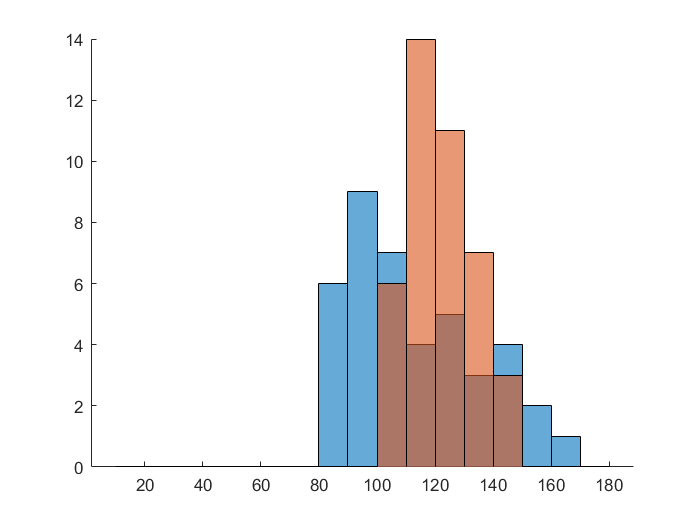

Extracting: dar-cmand1DR-ACC-20201213 - DSP22a ... [20 of 1599]  
Extracting: dar-cmand1DR-ACC-20210112 - DSP28a ... [80 of 1599]  
Extracting: dar-cmand1DR-ACC-20210112 - DSP14a ... [79 of 1599]  
Extracting: dar-cmand1DR-ACC-20201229 - DSP15a ... [40 of 1599]  
Extracting: jou-cmand1DR-ACC-20210103 - DSP20a ... [60 of 1599]  
Extracting: dar-cmand1DR-ACC-20201213 - DSP21b ... [19 of 1599]  
Extracting: dar-cmand1DR-ACC-20210112 - DSP12a ... [78 of 1599]  
Extracting: dar-cmand1DR-ACC-20201213 - DSP21a ... [18 of 1599]  
Extracting: dar-cmand1DR-ACC-20201229 - DSP14a ... [39 of 1599]  
Extracting: dar-cmand1DR-ACC-20201213 - DSP20a ... [17 of 1599]  
Extracting: jou-cmand1DR-ACC-20210103 - DSP18a ... [59 of 1599]  
Extracting: dar-cmand1DR-ACC-20201213 - DSP13a ... [16 of 1599]  
Extracting: dar-cmand1DR-ACC-20210112 - DSP11a ... [77 of 1599]  
Extracting: dar-cmand1DR-ACC-20201229 - DSP13b ... [38 of 1599]  
Extracting: jou-cmand1DR-ACC-20210103 - DSP17a ... [58 of 1599]  
Extracting

Unrecognized function or variable 'sdf_nostop_saccade'.

Error in acc_sfn_canceledAnalysis (line 191)
    {sdf_nostop_saccade(inputNeurons,:),sdf_noncanc_saccade(inputNeurons,:)},...

acc_sfn_canceledAnalysis